clc;
close all;
clear all;
pd = makedist('Nakagami','mu',9,'omega',6);
msg= random(pd,1000,1);
data=[];
t=0:.01:.99;
c=cos(2*pi*10*t);%carrier signal & it's a matrix of length 1X100(bcoz for each t, there's a c).let fc=10hz
for i=1:10
    if msg(i)<=0
        d=-1*ones(1,10);
    else
        d=ones(1,10);
    end
 data=[data d];   
end
 vbfsk=[];
for i=1:100
vbfsk=[vbfsk cos(2*pi*10*t+(msg(i)*2*pi*5*t))];
end

x = 1; % signal to transmit Eb = 1
T = 10000; %number of simulation runs per EbN0 %50000
N=10^6;
for EbN0 = 0:1:35 %dB
    NdB_EbN0= 10^(EbN0/10); 
    E_b = 1/(NdB_EbN0); 
    error = 0; %set error counter to 0
    error1=0;
    fun = makedist('Nakagami','mu',9,'omega',1);
    nakagami = random(fun,1000,1);
    fun_1 = makedist('Nakagami','mu',5,'omega',3);
    nakagami_1 = random(fun_1,1000,1);
        for t = 1:T %  count the errors
            gaussian_1 = sqrt(E_b/2)*randn; %noise for the first
            gaussian_2 = sqrt(E_b/2)*randn; %noise for the 2nd
            %rayleigh_1 = sqrt(0.5)*abs(randn + 1i*randn); %rayleigh noise
            %rayleigh_2 = sqrt(0.5)*abs(randn + 1i*randn);
            Added_noise_1=sqrt(E_b/2)*randn+sqrt(0.5)*abs(randn + 1i*randn);
            Added_noise_2=sqrt(E_b/2)*randn+sqrt(0.5)*abs(randn + 1i*randn);
            %Equal Gain combining
            EGC1 = x*vbfsk+gaussian_1; % Signal 1
            EGC2 = x*vbfsk+gaussian_2; % Signal 2
            EGC = 0.5*(EGC1+EGC2); 
            if EGC > 0 %define decision region as 0 
               error = error + 1;
           end
        end

    BER(EbN0+1) = error/(T);
end

% outage
gam0 = 5;
av_snr2=[];
av_snr1=[];
snr=[1:35];
fun_1 = makedist('Nakagami','mu',5,'omega',3);
    nakagami_1 = random(fun_1,1000,1);
    fun_2 = makedist('Nakagami','mu',5,'omega',2);
    nakagami_2 = random(fun_2,1000,1);
%nakagami_1=sqrt(0.5)*abs(randn(1000,1)+1i*randn(1000,1)); %rayleigh channel 1
%nakagami_2=sqrt(0.5)*abs(randn(1000,1)+1i*randn(1000,1)); %rayleigh channel 2
%%Adding Noise
A=[];
B=[];
for i=1:length(snr)
    sig1=awgn(nakagami_1,snr(i));
    A=[A,sig1];
    sig2=awgn(nakagami_2,snr(i));
    B=[B,sig2];
end
n=size(A);
for k=1:n(2)
    asn1=A(:,k);
    asn2=B(:,k);
    avg=0;
    aa=0;
for i=1:length(B)
    wgt=(abs(asn1(i))^2)+(abs(asn2(i))^2)/2;
    avg=avg+wgt;
    aa=aa+abs(asn1(i)^2);
end
av_snr2=[av_snr2,avg];
av_snr1=[av_snr1,aa];
end
gr = gam0./(snr.*av_snr2);
gr1 = gam0./(snr.*av_snr1);
for i = 1:length(gr)
    pout2(i) = (1-(exp(-2*gr(i)))-((sqrt(pi*gr(i)))*(exp(-gr(i)))))*(1-2*(erfc(sqrt(gr(i)))));
    pout1(i) = (1-(exp(-2*gr1(i)))-((sqrt(pi*gr1(i)))*(exp(-gr1(i)))))*(1-2*(erfc(sqrt(gr1(i)))));
end
%plotting of figure

subplot(411);
plot(msg);
title('nakagami m data');

subplot(412);
plot(data);axis([0 100 -1.5 1.5])
title('Digital data');
subplot(413)
plot(c);axis([0 100 -1.5 1.5])
title('Unmodulated carrier');
 
%disp(data);
disp(vbfsk);

  Columns 1 through 19

    1.0000    0.2480   -0.8770   -0.6831    0.5381    0.9500   -0.0668   -0.9832   -0.4209    0.7744    0.8050   -0.3750   -0.9911   -0.1166    0.9332    0.5796   -0.6457   -0.8999    0.1993

  Columns 20 through 38

    0.9987    0.2962   -0.8518   -0.7188    0.4953    0.9644   -0.0168   -0.9728   -0.4658    0.7417    0.8337   -0.3282   -0.9965   -0.1662    0.9141    0.6196   -0.6067   -0.9206    0.1500

  Columns 39 through 57

    0.9950    0.3436   -0.8245   -0.7526    0.4512    0.9765    0.0332   -0.9600   -0.5094    0.7073    0.8603   -0.2805   -0.9994   -0.2153    0.8926    0.6581   -0.5662   -0.9390    0.1004

  Columns 58 through 76

    0.9888    0.3901   -0.7952   -0.7846    0.4060    0.9860    0.0832   -0.9448   -0.5518    0.6710    0.8847   -0.2321   -0.9999   -0.2639    0.8690    0.6950   -0.5242   -0.9550    0.0505

  Columns 77 through 95

    0.9800    0.4357   -0.7639   -0.8147    0.3598    0.9931    0.1329   -0.9272   -0.5929    0.6331    0.90

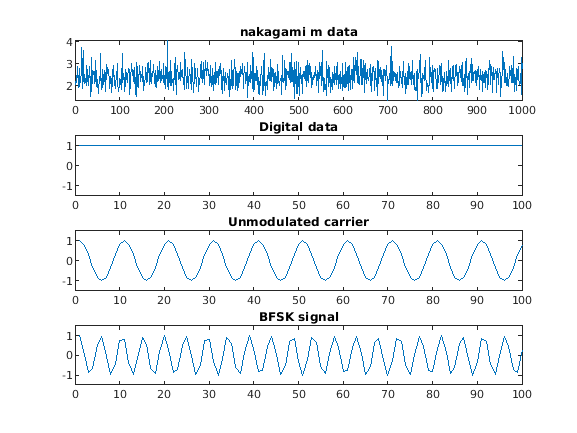

subplot(414);
plot(vbfsk);axis([0 100 -1.5 1.5])
title('BFSK signal');

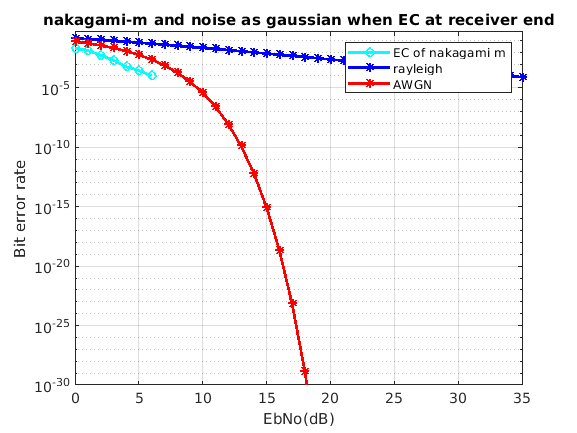

figure
EbNo=0:1:35; %changed from 10
linear_EbNo = 10.^(EbNo/10);
theoryBerAWGN = 0.5*erfc(sqrt(10.^(EbNo/10)));
theoryBer = 0.5.*(1-sqrt(linear_EbNo ./(linear_EbNo +1)));
semilogy(EbNo,BER,'c-o',EbNo,theoryBer,'b*-',EbNo,theoryBerAWGN,'r*-','linewidth',2); % plot EG BER vs EbNo
hold on;
grid on;
axis([0 35 10^-30 0.5])
legend('EC of nakagami m','rayleigh','AWGN');
xlabel('EbNo(dB)') %Label for x-axis
ylabel('Bit error rate') %Label for y-axis
title('nakagami-m and noise as gaussian when EC at receiver end');

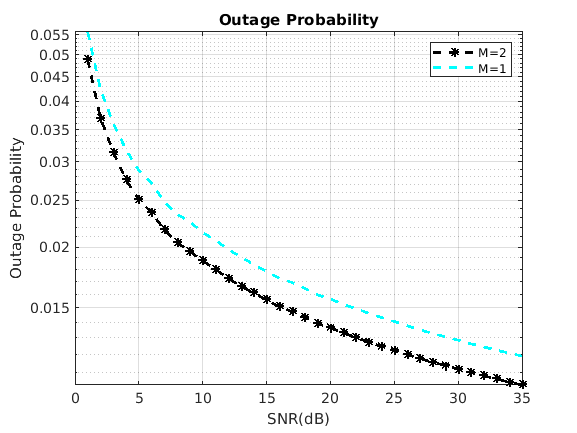


figure()
semilogy(snr,pout2,'k*--',snr,pout1,'c--','linewidth',2);

hold on;

grid on;
 xlabel('SNR(dB)');
 ylabel('Outage Probability');
 legend('M=2','M=1')
title('Outage Probability')